# Stima in frequenza 

L'obiettivo è stimare la risposta in frequenza andando a inserire un segnale eccitante attorno a un punto di equilibrio.

Il segnale eccitante deve un contenuto frequenziale nella banda dove ci interessa stimare.

## Definizione punto di equlibrio

Visto che la realtà non è lineare, la stima vale solo attorno ad un punto di equilibrio. Nel nostro sistema le maggiori nonlinearità sono

- le saturazioni (dobbiamo starci lontano)

- l'attrito statico, stimiamo il sistema con una velocità sempre diversa da zero. In molte macchine, occorre tenere presente i limiti di giunto. In quel caso si può aggiungere una portante in bassa frequenza 

clear all;close all;clc;
motorecarico
mdl = 'StimaFrenquenza';
open_system(mdl)

Selezionare i punti di ingresso e uscita (vedi schema simulink)

io=getlinio(mdl);

Calcola il punto di equilibrio del sistema (attendo 20 secondi per esaurire il transitorio)

operationg_point=findop(mdl,20);

## Calcolo segnale eccitante

il segnale eccitante scelto è una serie di sinusoidi

Le sinusoidi devono avere frequenza inferiore alla frequenza di Nyquist

st=1e-3;
wmax=pi/st

wmax = 3.1416e+03

è consigliabile avere più sinusoidi nella zona a bassa frequenza e dove ci sono le risonanze (si può fare una prima stima veloce per capire dove sono i range d'interesse)

Le sinusoidi a bassa frequenza hanno periodi lunghi (ovviamente!) per cui il sistema riesce a terminare il transitorio già dopo un periodo, e bastano pochi periodi per avere tanti dati.

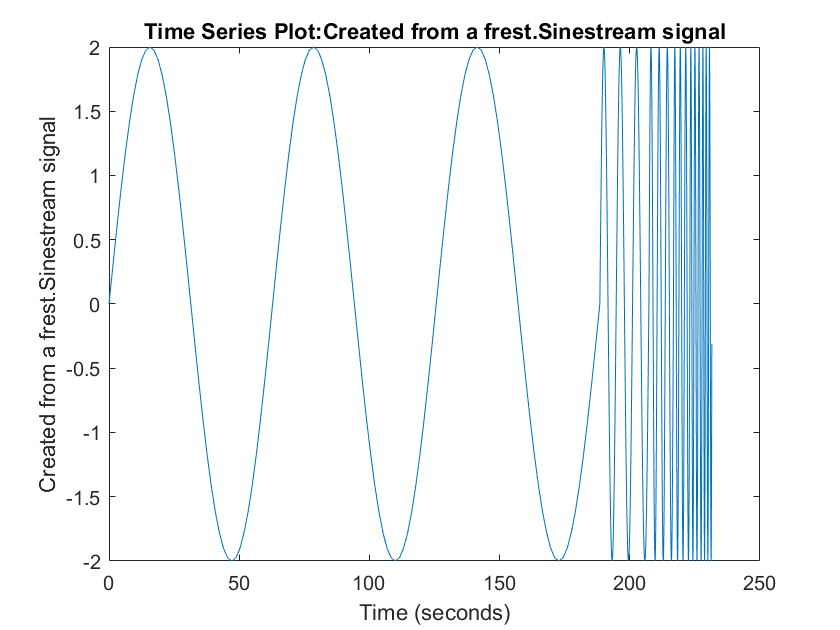

freqs1 = [0.1 1 2 3 4 5]'; % frequenze [rad/s]
amps1 = 2*ones(length(freqs1),1); % ampiezza
ramp1 = 0*ones(length(freqs1),1); % numero di sinusoidi "a rampa" (durante la rampa l'ampiezza cresce da 0 al valore specificato)
settle1 = 0*ones(length(freqs1),1); % numero sinusoidi di assestamento "da scartare"
pds1 = 3*ones(length(freqs1),1); % numero di periodi in cui la sinusoide è ripetuta

input = frest.Sinestream('Frequency',freqs1,...
    'Amplitude',amps1,...
    'RampPeriods',ramp1,...
    'SettlingPeriods',settle1,...
    'NumPeriods',pds1);
figure
plot(input)

Nel range di media frequenza posso usare più periodi, e posso infittire i dati attorno alle frequenze di risonanza/antirisonanza spaziando le frequenze in scala logaritmica

freqs2 = logspace(log10(10),log10(100),100)'; % freq. spaziate logaritmicamente
amps2 = 2*ones(length(freqs2),1);
ramp2 = 0*ones(length(freqs2),1);
settle2 = 0*ones(length(freqs2),1);
pds2 = 4*ones(length(freqs2),1);

Ad alta frequenza posso dare una spazzolata spaziando le frequenze in scala logaritmica, può essere consigliato ridurre l'ampiezza del segnale per non far saturare gli attuatori

freqs3 = logspace(log10(120),log10(wmax),20)'; % freq. spaziate logaritmicamente

amps3 = 2*ones(length(freqs3),1);
ramp3 = 0*ones(length(freqs3),1);
settle3 = 2*ones(length(freqs3),1);
pds3 = 5*ones(length(freqs3),1);

Il segnale complessivo è dato dalla somma delle varie sinusoidi

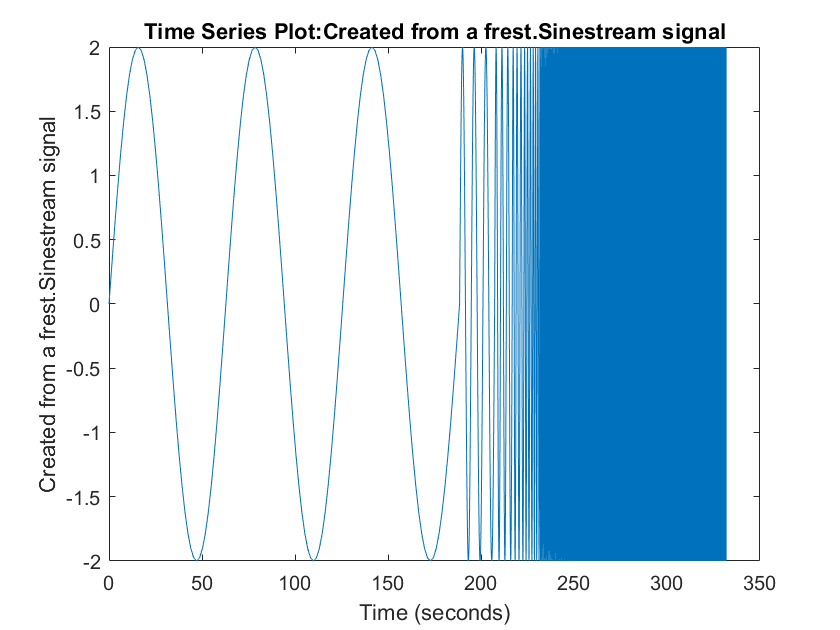

freqs=[freqs1;freqs2;freqs3];
amps=[amps1;amps2;amps3];
ramp=[ramp1;ramp2;ramp3];
settle=[settle1;settle2;settle3];
pds=[pds1;pds2;pds3];
input = frest.Sinestream('Frequency',freqs,...
    'Amplitude',amps,...
    'RampPeriods',ramp,...
    'SettlingPeriods',settle,...
    'NumPeriods',pds);
figure
plot(input)

é possibile utilizzare anche altri segnali come la[ pseudorandom binary sequence](https://en.wikipedia.org/wiki/Pseudorandom_binary_sequence), il [chirp](https://it.wikipedia.org/wiki/Chirp), o la somma di molte sinuosoidi che permettono di fare esperimenti brevi. Tuttavia la spazzolata di sinuosoidi usata in questo caso permette di avere i dati della risposta in frequenza frequenza per frequenza, ottenendo spesso migliori risultati.

## Esperimento

simuliamo il sistema attorno al punto di equilibrio con il segnale eccitante

[sysest,simout] = frestimate(mdl,operationg_point,io,input);

sysest è la risposta in frequenza calcolata, simout è l'output completo della simulazione.

## Risultati e uso della risposta in frequenza

L'esperimento consente di ottenere la risposta in frequenza (una stima della risposta in frequenza!), che può essere usata così com'è per le tarature che non richiedono la conoscenza della funzione di trasferimento (loop shaping, ottimizzazione).

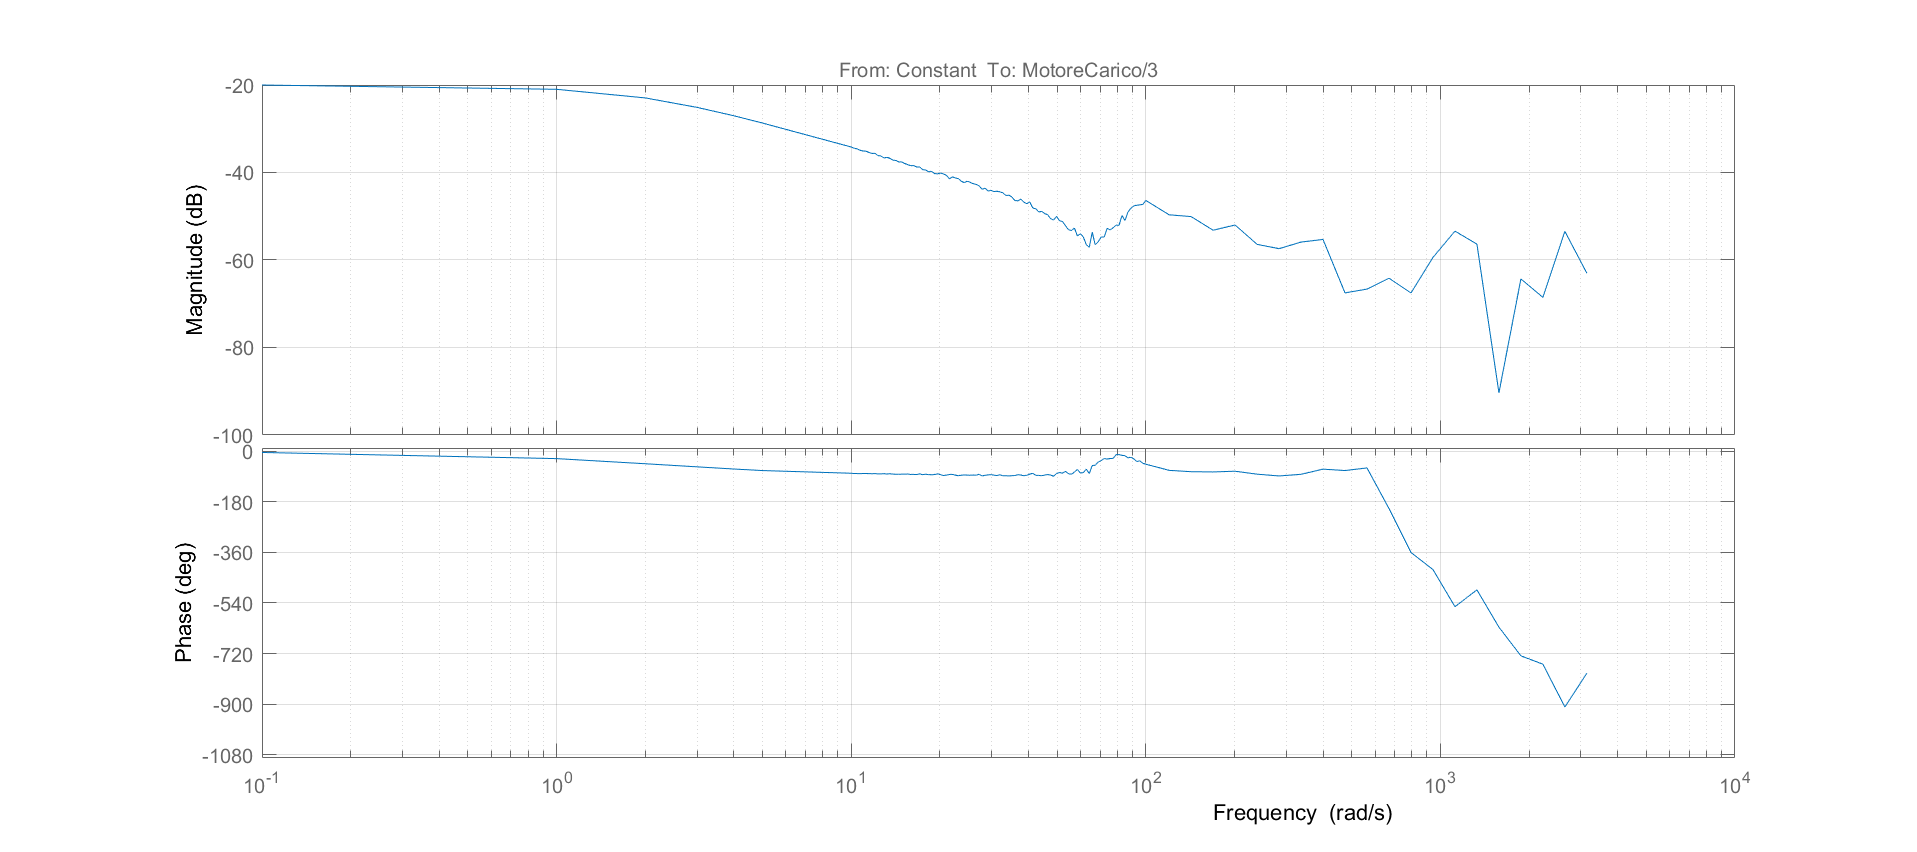

figure('Position',[1 1 1800 800])
bode(sysest)
grid on

è possibile anche analizzare l'output della simulazione con il tool dedicato (vedi figura a parte)

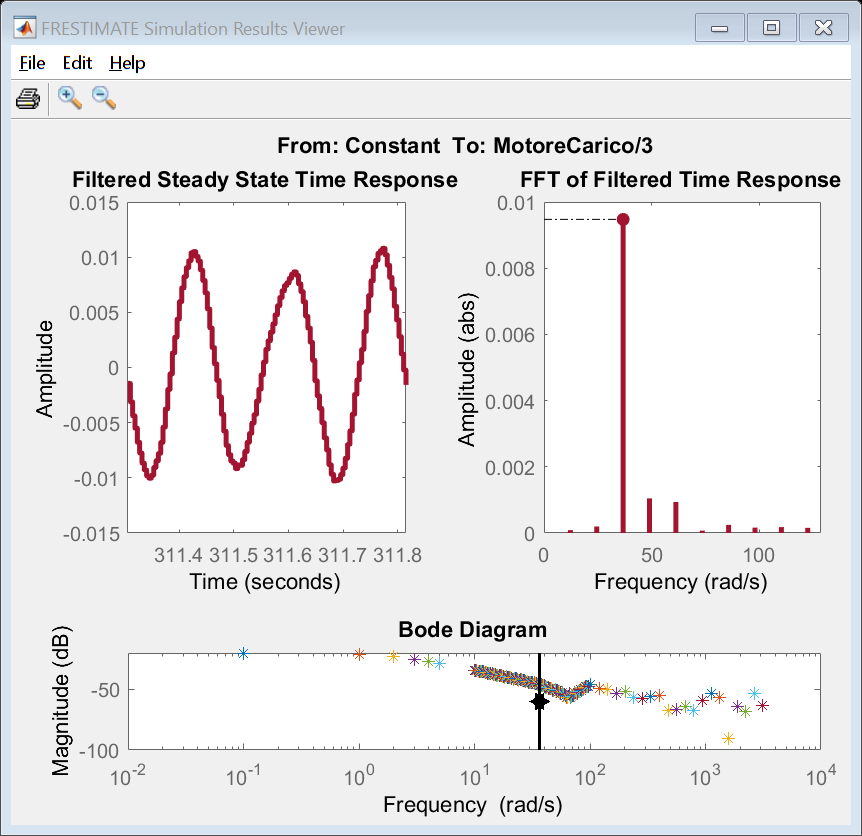

figure
frest.simView(simout,input,sysest)

## Stima del modello

data la risposta in frequenza, possiamo stimare il modello del sistema.

Esistono diversi tool, dal semplice "mettere i poli e gli zeri a mano" a tool automatizzati. Le linee guida sono sempre: 

- più il modello è semplice meglio è

- validare il risultato!

Scegliendo *ssest*, posso stimare il sistema usando:

modello_stimato=ssest(sysest)


modello_stimato =
  Continuous-time identified state-space model:
      dx/dt = A x(t) + B u(t) + K e(t)
       y(t) = C x(t) + D u(t) + e(t)
 
  A = 
                x1          x2          x3          x4          x5          x6          x7
   x1     0.004576     -0.0109    0.003952     -0.3327      -0.174     -0.4293       1.057
   x2    1.571e-08     -0.2289       19.79   1.324e-09  -1.644e-10   5.819e-09  -8.211e-10
   x3    1.128e-08      -19.79     -0.2289      -1.022     -0.5343      -1.319       3.247
   x4   -1.972e-06  -3.676e-06  -6.616e-06      -19.05        88.5   5.326e-07   2.506e-07
   x5   -5.621e-06   2.473e-06   -1.83e-05       -88.5      -19.05       -42.7       105.2
   x6   -0.0003438   3.878e-06   -0.001056   0.0004627    -0.03429       15.69        1101
   x7    7.864e-05   1.896e-05   0.0002414    0.002738    0.007813       -1101       15.69
   x8    0.0001813   3.738e-06   0.0005567   0.0005768     0.01803     0.08767     0.03012
   x9    2.792e-05  -5.366e-0

che mi stima un sistema con ordine

order(modello_stimato)

ans = 10

e mette i poli e li zeri:

zpk(modello_stimato)


ans =
 
  From input "Constant" to output "MotoreCarico/3":
                                                                                               
   0.4925 (s-0.0008034) (s^2 + 0.4699s + 391.1) (s^2 + 20.8s + 4937) (s^2 + 290.7s + 1.069e06) 
                                                                                               
                                                               (s^2 - 280.5s + 5.415e06)       
                                                                                               
  ----------------------------------------------------------------------------------------------
                                                                                                
  (s+1.995) (s-0.004578) (s^2 + 0.4578s + 391.7) (s^2 + 38.1s + 8196) (s^2 - 31.35s + 1.213e06) 
                                                                                                
                                                              (s^2 - 53

Otteniemo quindi un sistema instabile (anche se fitta benissimo la risposta in frequenza).

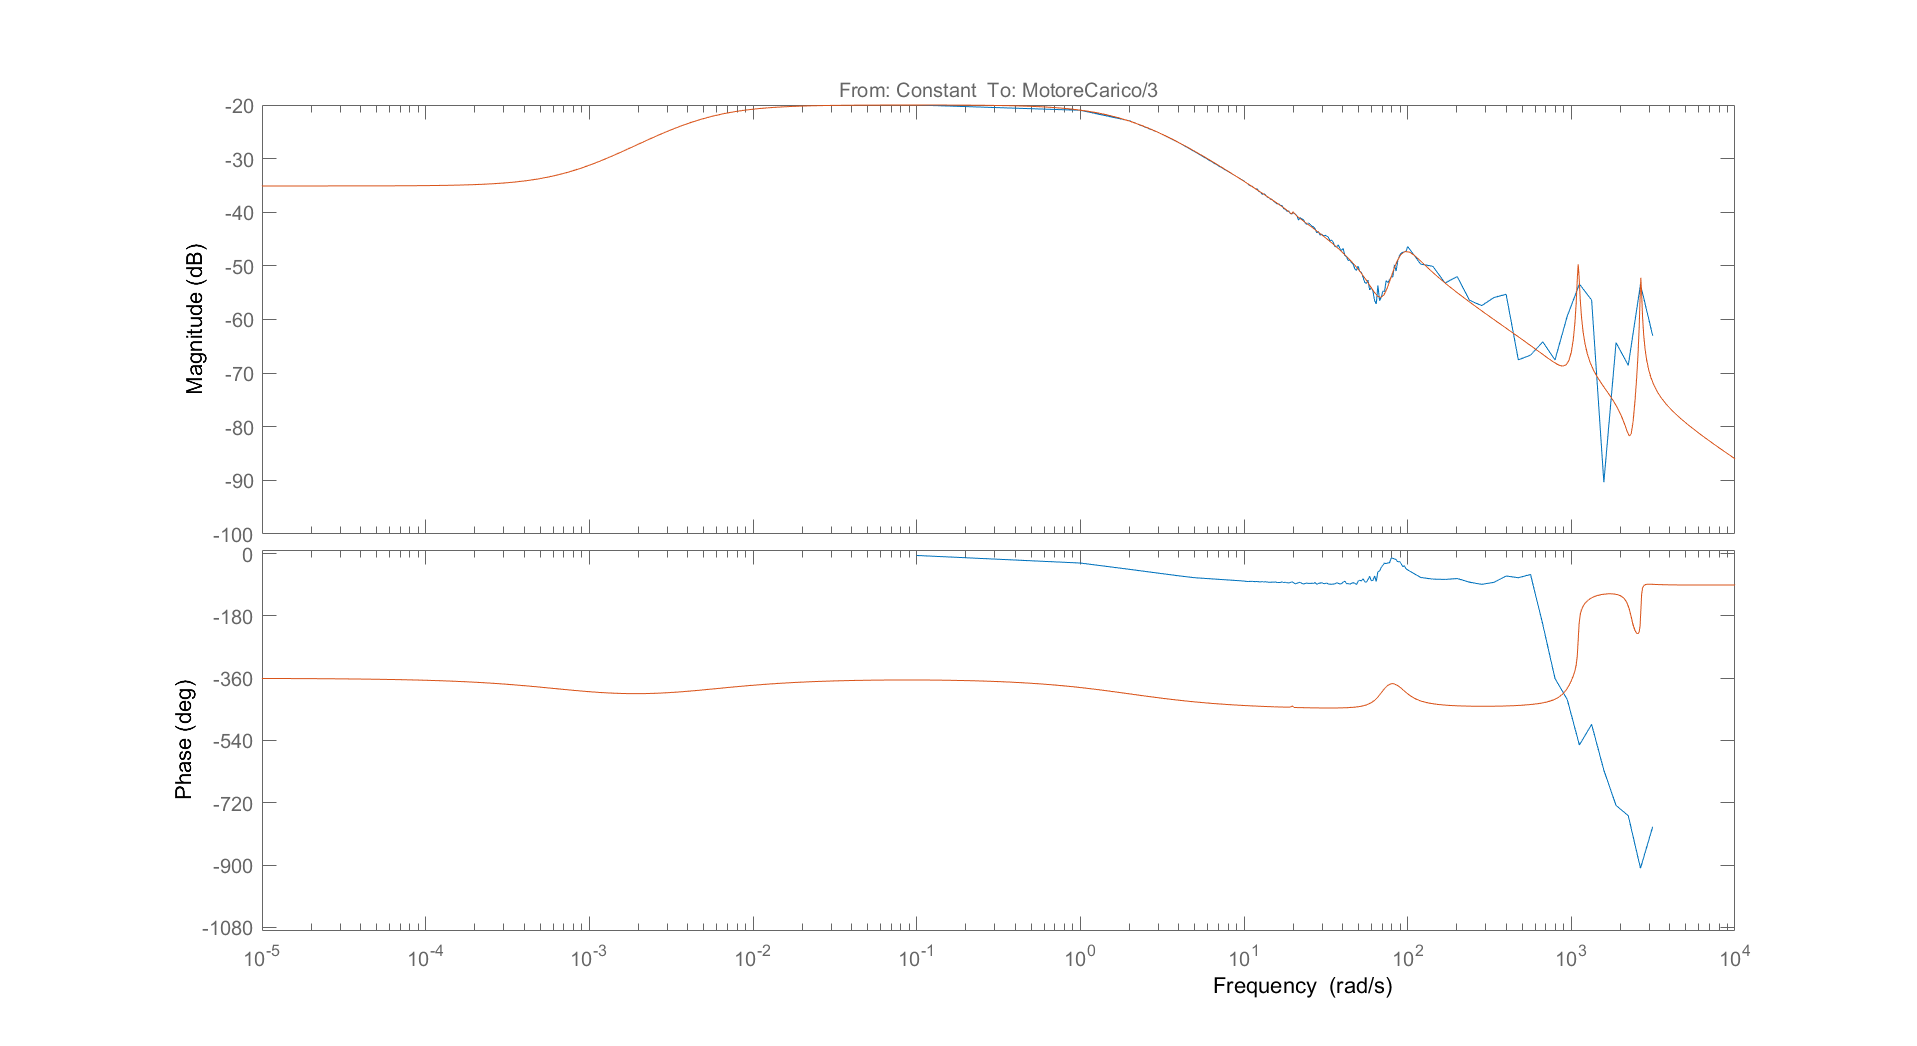

figure('Position',[1 1 1800 800])
bode(sysest,modello_stimato)

Ragionamo  sulla risposta del sistema

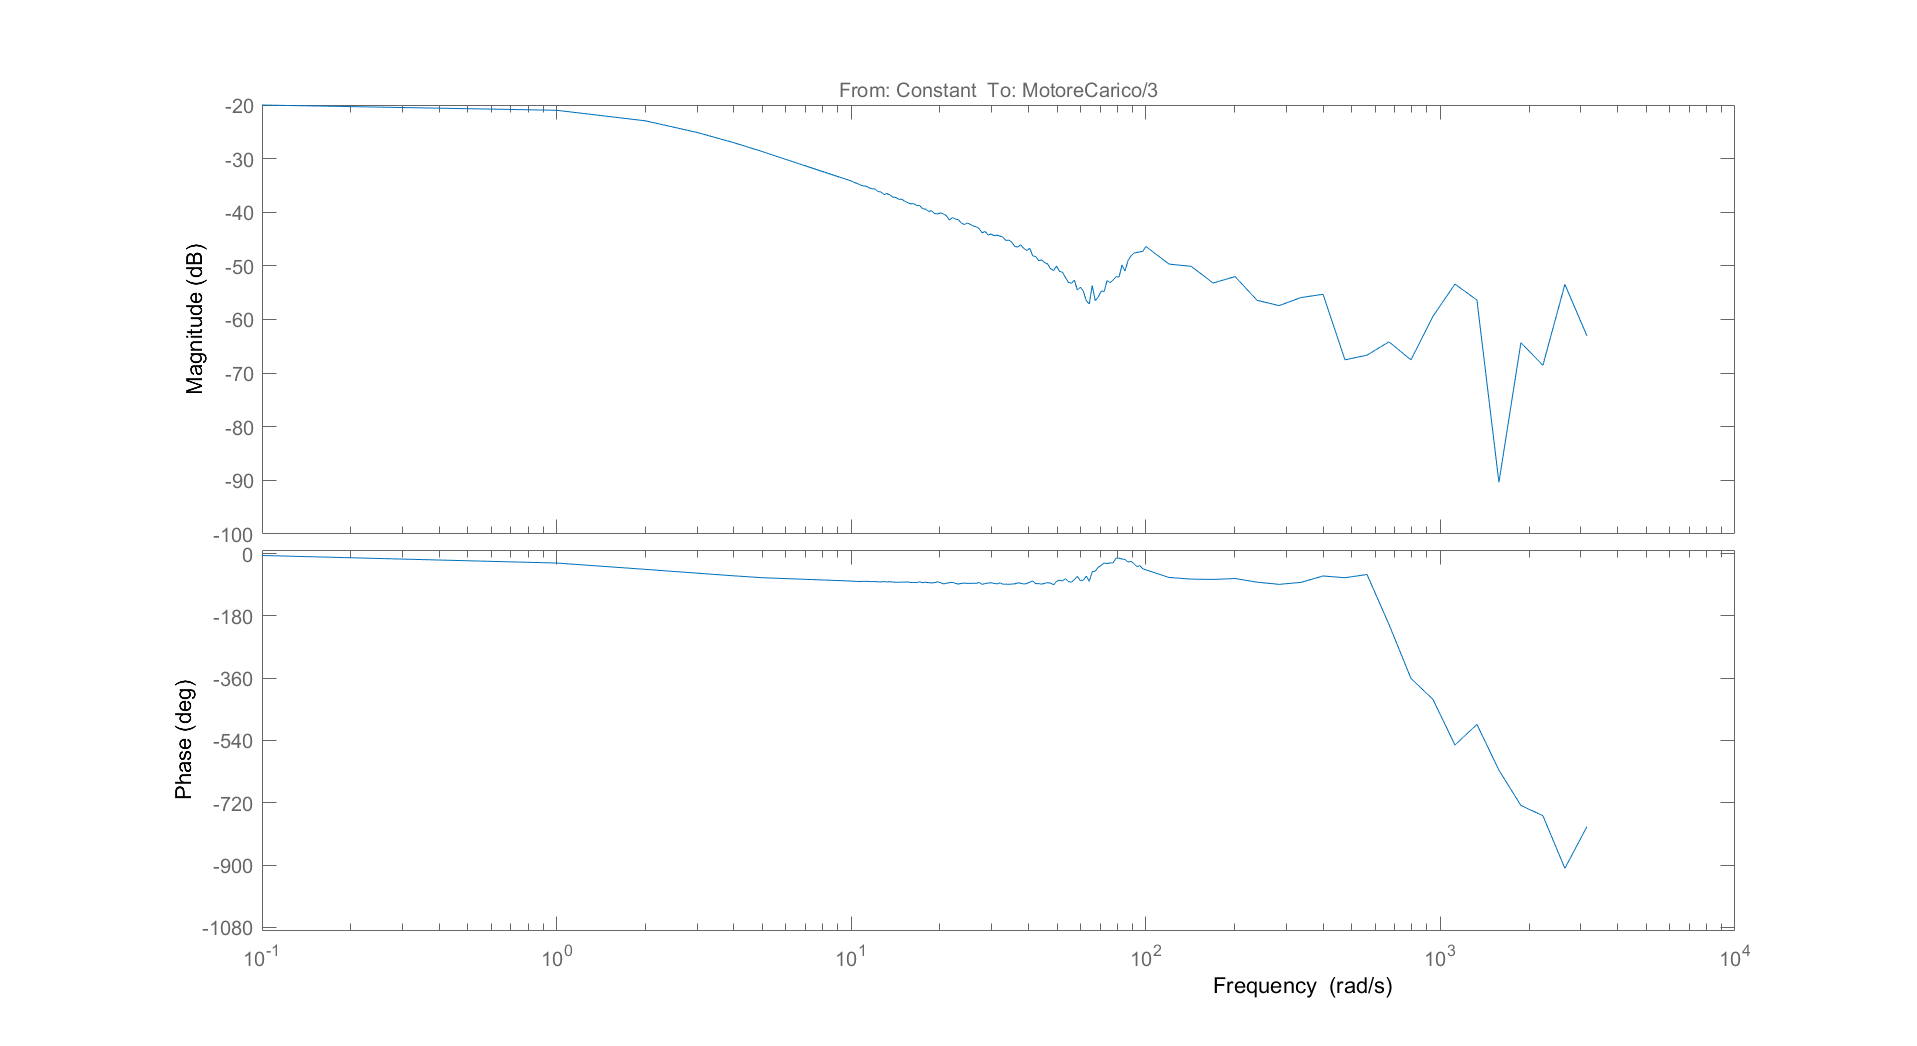

figure('Position',[1 1 1800 800])
bode(sysest)

ha una coppia poli complessi coniugati / zeri complessi coniugati (il "filtro" notch attorno a 70-100 rad/s), e (almeno) un polo in bassa frequenza

Scelgo quindi un sistema di ordine 3 

modello_3_ordine_stimato=ssest(sysest,3);

che mi stima un sistema con ordine

order(modello_3_ordine_stimato)

ans = 3

e mette i poli e li zeri:

zpk(modello_3_ordine_stimato)


ans =
 
  From input "Constant" to output "MotoreCarico/3":
   0.33371 (s^2 + 21.59s + 4994)
  -------------------------------
  (s+1.988) (s^2 + 37.92s + 8359)
 
Continuous-time zero/pole/gain model.



damp(modello_3_ordine_stimato)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -1.99e+00                 1.00e+00       1.99e+00         5.03e-01    
 -1.90e+01 + 8.94e+01i     2.07e-01       9.14e+01         5.27e-02    
 -1.90e+01 - 8.94e+01i     2.07e-01       9.14e+01         5.27e-02    


minreal(zpk(modello_lineare)) % zpk 


ans =
 
  From input "Coppia" to output "Velocità motore":
   0.33333 (s^2 + 13.33s + 3333)
  -------------------------------
  (s+1.667) (s^2 + 28.33s + 6664)
 
Continuous-time zero/pole/gain model.



Possiamo vedere come le due risposte siano strutturalmente simili.

Anche analizzando la risposta in frequenza

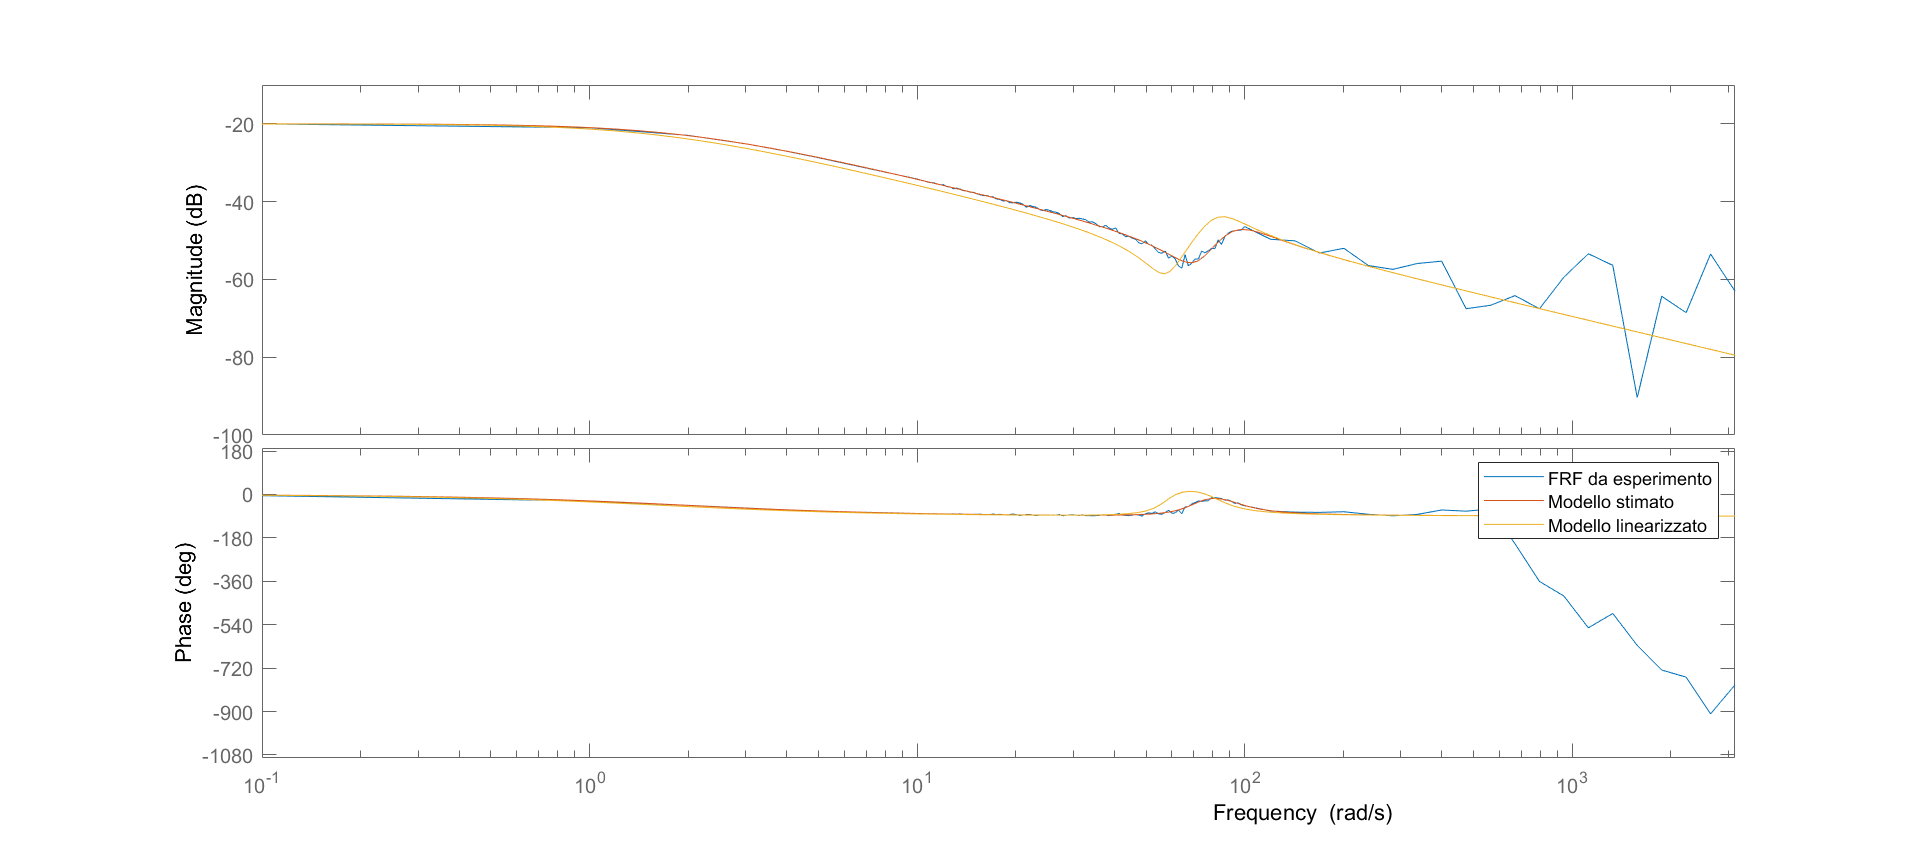

figure('Position',[1 1 1800 800])
bode(sysest,modello_3_ordine_stimato,modello_lineare)
legend('FRF da esperimento','Modello stimato','Modello linearizzato')
xlim([min(freqs) max(freqs)])

le risposte sono molto simili, bisogna considerare che:

- il modello lineare non tiene conto dell'attrito, che "smorzano" le oscillazioni

- la risposta in frequenza acquisita è campionata, quindi ad alta frequenza abbiamo l'effetto della discretizzazione

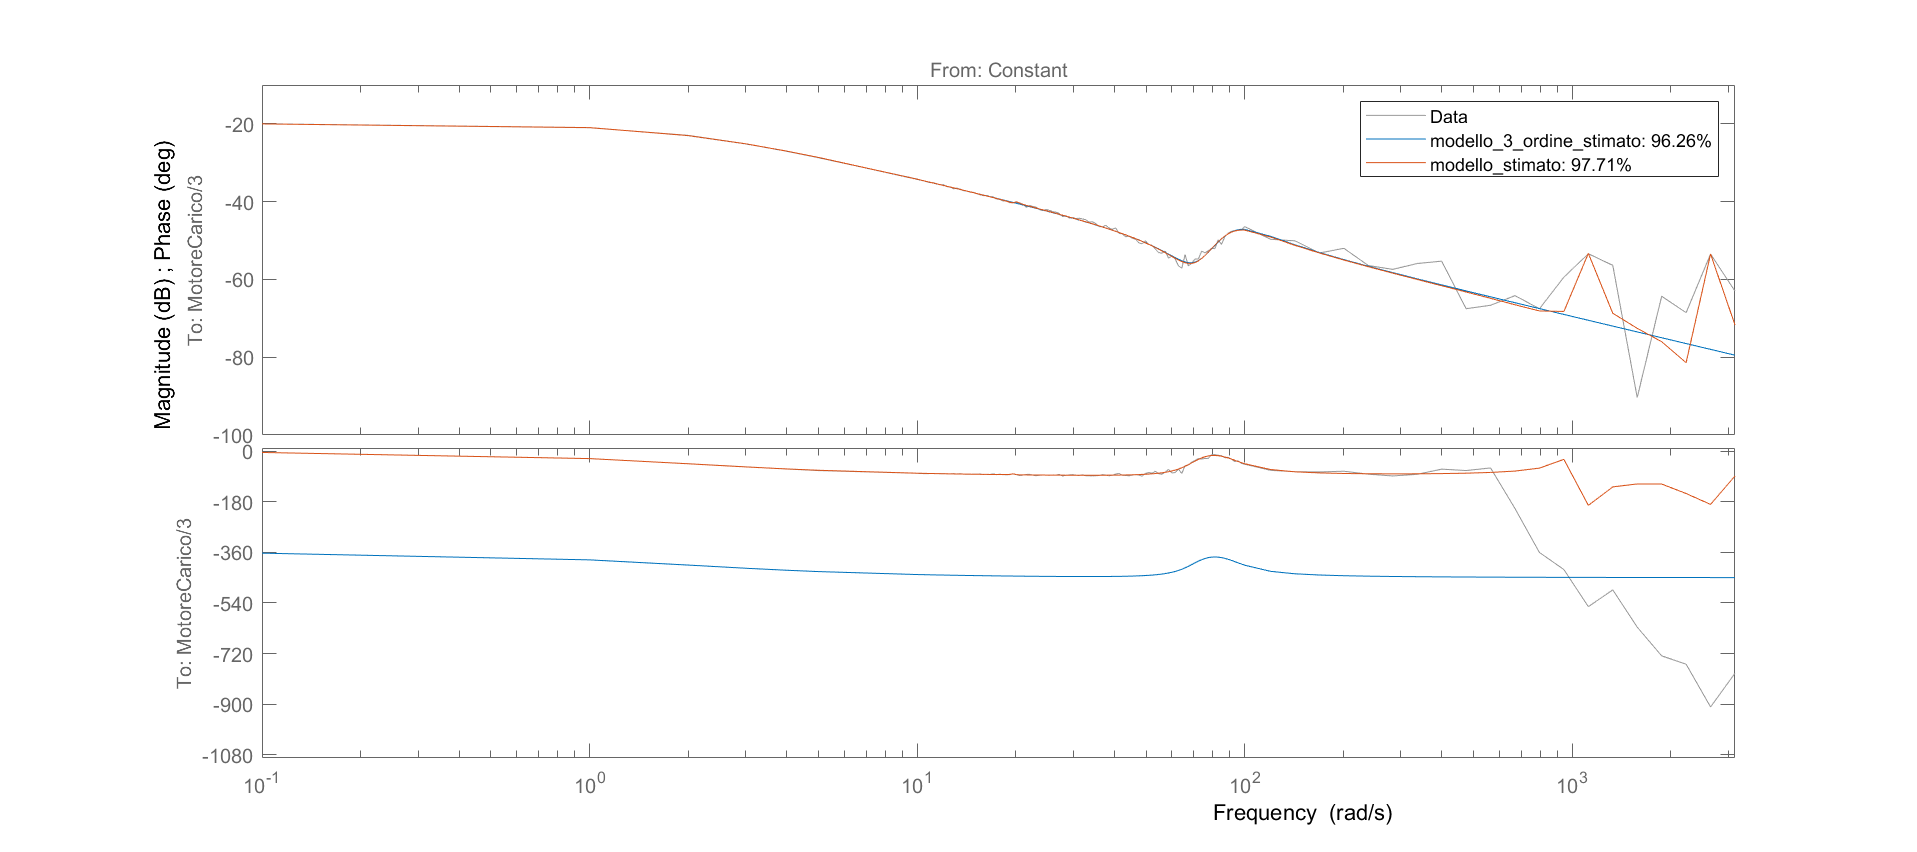

figure('Position',[1 1 1800 800])
compare(sysest,modello_3_ordine_stimato,modello_stimato)

## Bonus track: perché un terz'ordine?

nelle equazioni della molla quello che conta è la posizione relativa fra motore e carico. Se effettuiamo un cambio di variabili, prendendo come variabile di stato la deflessione della molla $q_m-q_c$ abbiamo:

Tlin=[1 0 0 0;1 -1 0 0;0 0 1 0;0 0 1 -1];
modello_lineare_cambio_variabili=ss2ss(modello_lineare,Tlin);
modello_lineare_cambio_variabili.StateName={'Pos Motore' 'deflessione' 'Vel Motore','vel deflessione'}


modello_lineare_cambio_variabili =
 
  A = 
                   Pos Motore   deflessione    Vel Motore  vel deflessi
   Pos Motore               0             0             1             0
   deflessione              0             0             0             1
   Vel Motore               0         -3333        -3.333        -13.33
   vel deflessi             0         -6667        -3.333        -26.67
 
  B = 
                 Coppia
   Pos Motore         0
   deflessione        0
   Vel Motore    0.3333
   vel deflessi  0.3333
 
  C = 
                   Pos Motore   deflessione    Vel Motore  vel deflessi
   Velocità mot             0             0             1             0
 
  D = 
                 Coppia
   Velocità mot       0
 
Continuous-time state-space model.



Si può vedere come la posizione del motore non influenzi le altre variabili (è solo l'integrale della velocità motore), il modello stimato con ssest ha come uscita la velocità, per cui bastano 3 stati per descriverlo.

## Stima a mano

proviamo a stimare a mano della velocità del motore

stima del guadagno:

guadagno=abs(freqresp(sysest,min(freqs)))

guadagno = 0.1000

posiziono la pulsazione naturale dei poli in circa 10 rad/s e degli zeri in circa 10 rad/s

wn=93.8

wn = 93.8000

wz= 66

wz = 66

sceglo smorzamento poli e zeri

xi_p=0.29

xi_p = 0.2900

xi_z= 0.15

xi_z = 0.1500

tau_p=0.5;

il sistema sarà quindi:

s=tf('s');
sys_stimato=zpk(guadagno*(s^2/wz^2+2*xi_z*s/wz+1)/(s^2/wn^2+2*xi_p*s/wn+1)/(tau_p*s+1))


sys_stimato =
 
  0.40388 (s^2 + 19.8s + 4356)
  ----------------------------
   (s+2) (s^2 + 54.4s + 8798)
 
Continuous-time zero/pole/gain model.



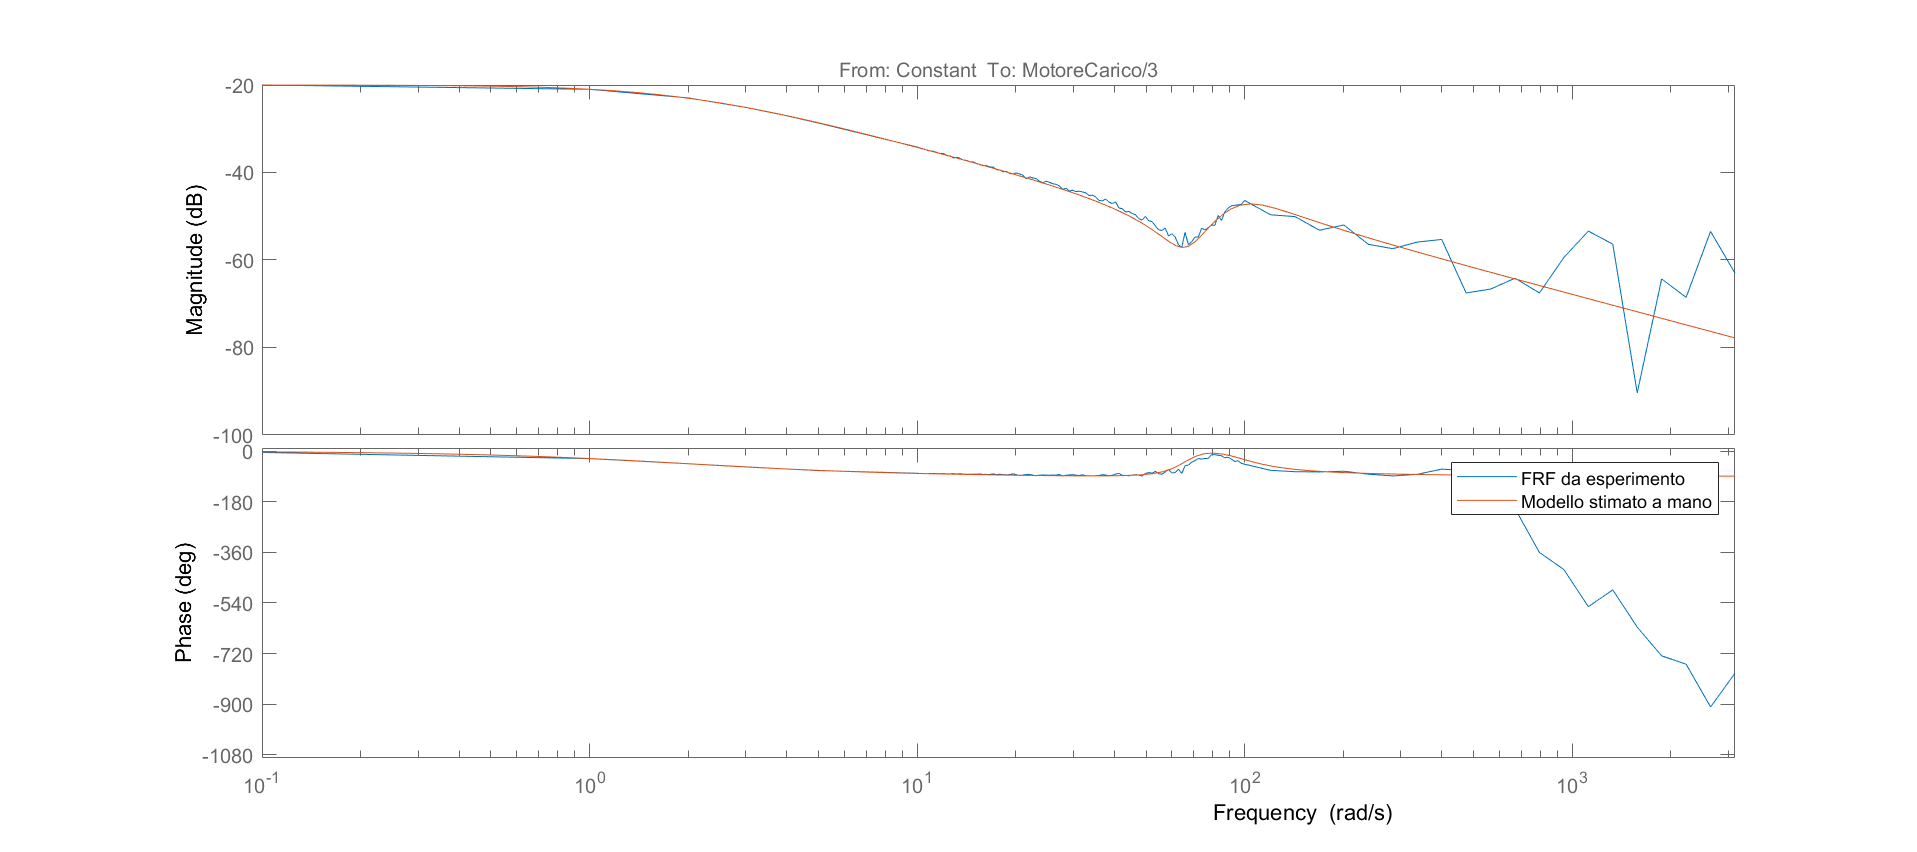

figure('Position',[1 1 1800 800])
bode(sysest,sys_stimato)
legend('FRF da esperimento','Modello stimato a mano')
xlim([min(freqs) max(freqs)])

## Validazione!

Creaiamo un altro segnale con frequenza e ampiezze diverse:

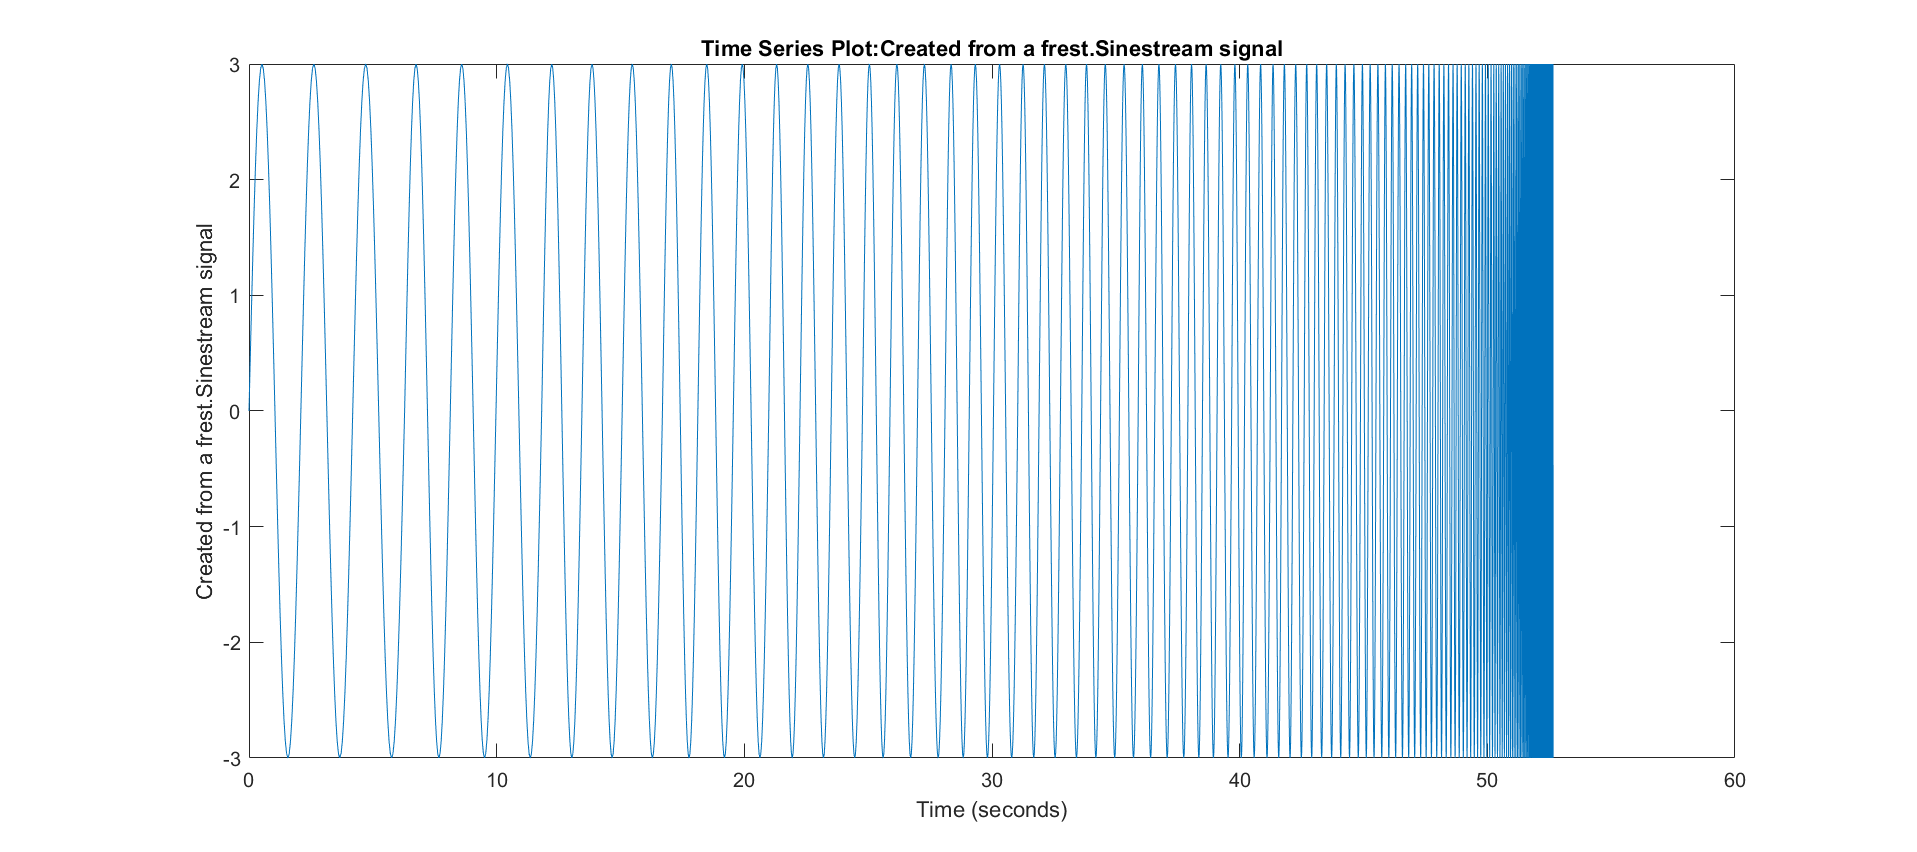

freqs_val1 = logspace(log10(3),log10(1500),50)';
amps_val1 = 3*ones(length(freqs_val1),1);
ramp_val1 = 0*ones(length(freqs_val1),1);
settle_val1 = 0*ones(length(freqs_val1),1);
pds_val1 = 3*ones(length(freqs_val1),1);

input_val = frest.Sinestream('Frequency',freqs_val1,...
    'Amplitude',amps_val1,...
    'RampPeriods',ramp_val1,...
    'SettlingPeriods',settle_val1,...
    'NumPeriods',pds_val1);

figure('Position',[1 1 1800 800])
plot(input_val)

[sys_val,simout_val] = frestimate(mdl,operationg_point,io,input_val);

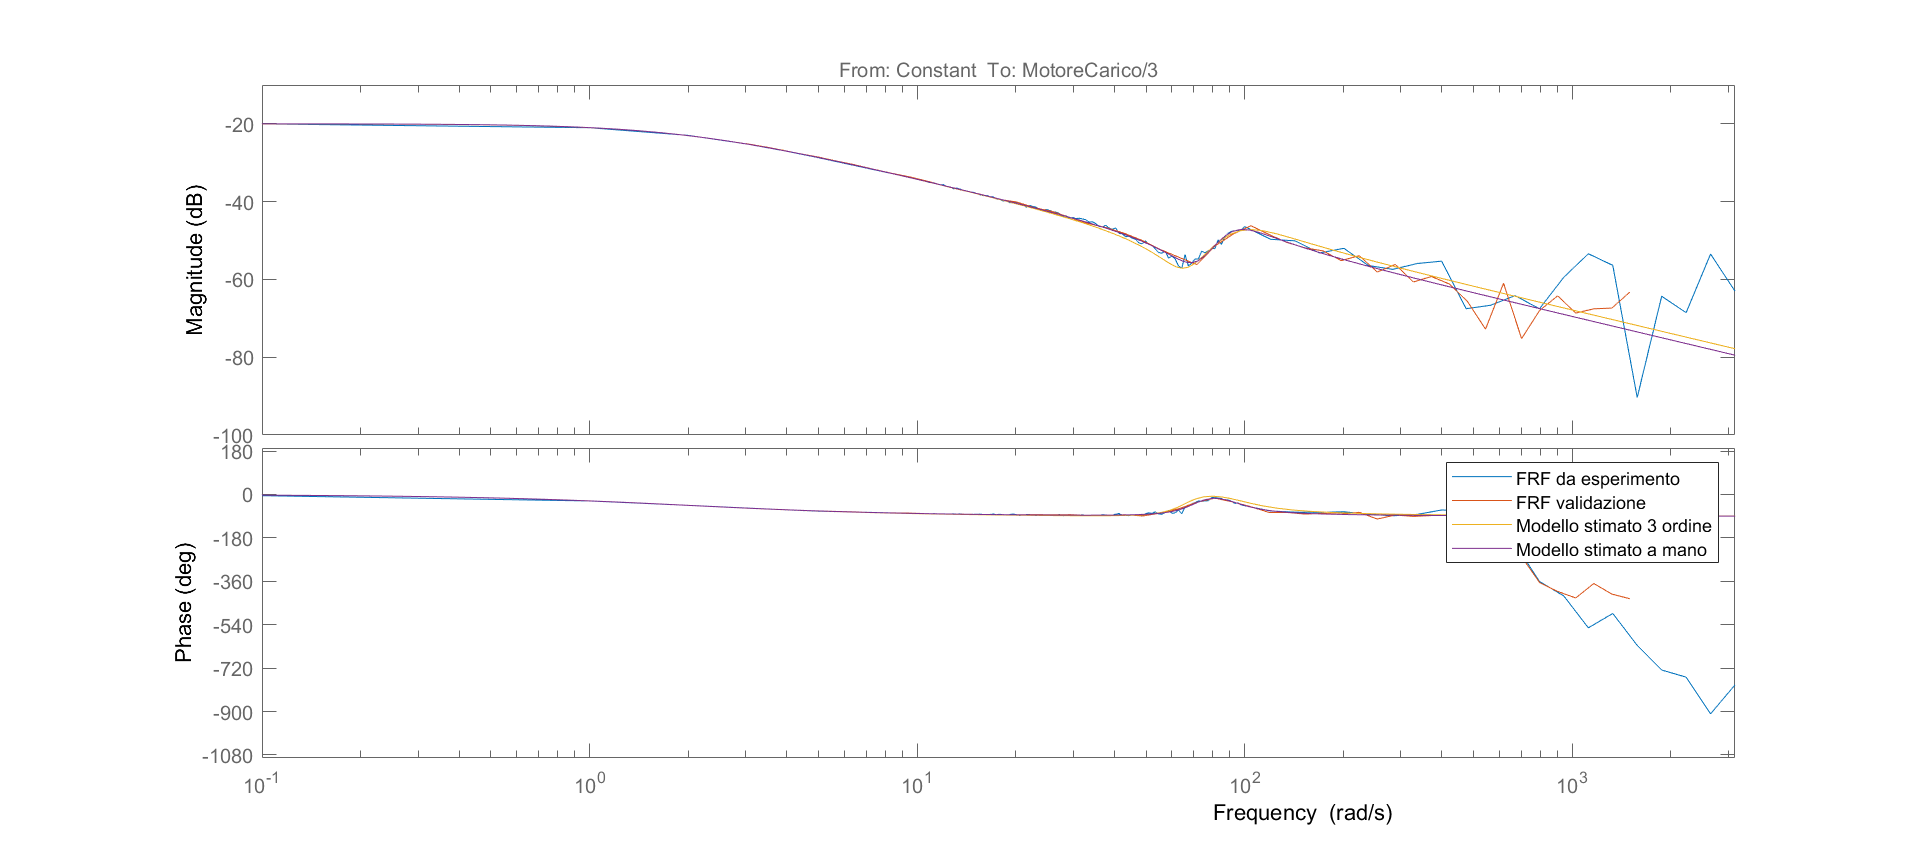

figure('Position',[1 1 1800 800])
bode(sysest,sys_val,sys_stimato,modello_3_ordine_stimato)
legend('FRF da esperimento','FRF validazione','Modello stimato 3 ordine','Modello stimato a mano')
xlim([min(freqs) max(freqs)])

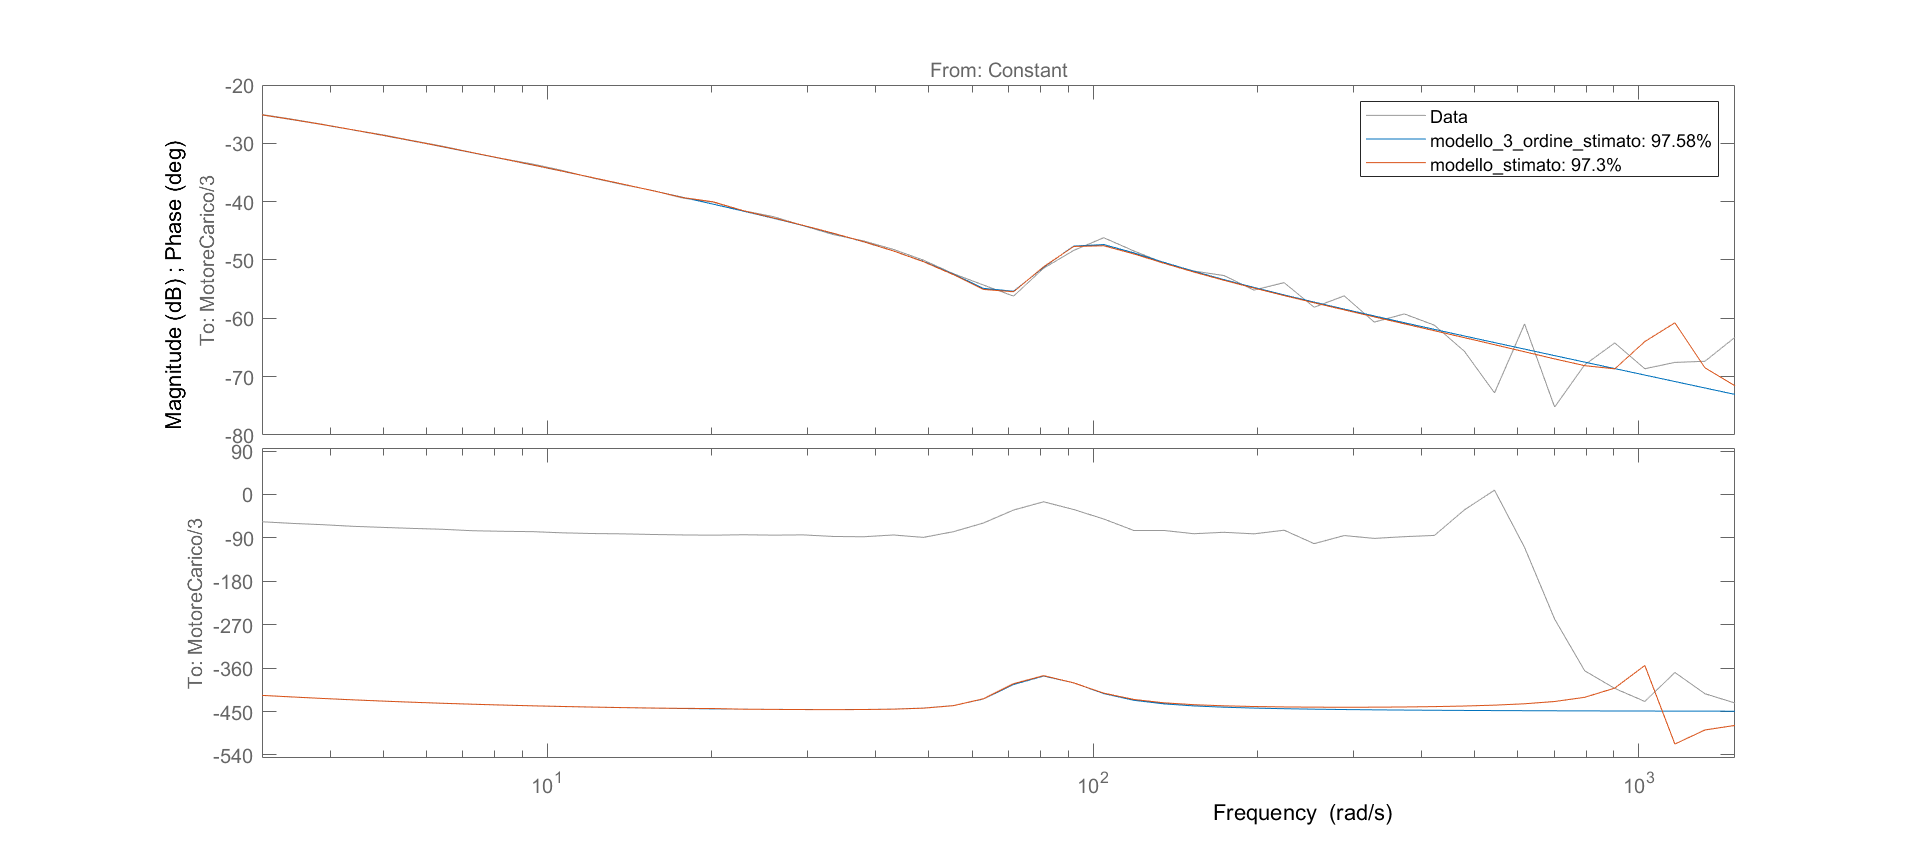

figure('Position',[1 1 1800 800])
compare(sys_val,modello_3_ordine_stimato,modello_stimato)